%Read 5 by 5 image
%Harris Corner Detection
Image = imread('./corner.jpg')

Image = 5×5 uint8 matrix
   255   245   255     0     3
   231   240   255     0    14
   255   255   239     8     0
     0    12    14     0     3
    27    14     3     7    10


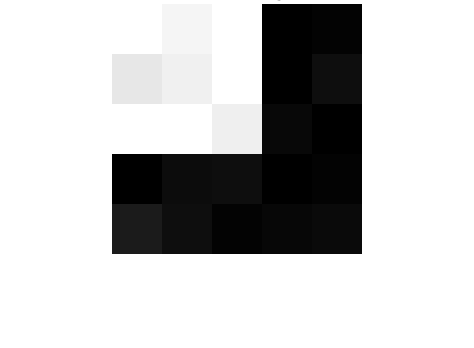

imshow(Image, InitialMagnification=5000)
title('Input Image')

corners = detectHarrisFeatures(Image,"FilterSize",3)

corners =   cornerPoints with properties:

    Location: [3.0040 3.0244]
      Metric: 0.1409
       Count: 1


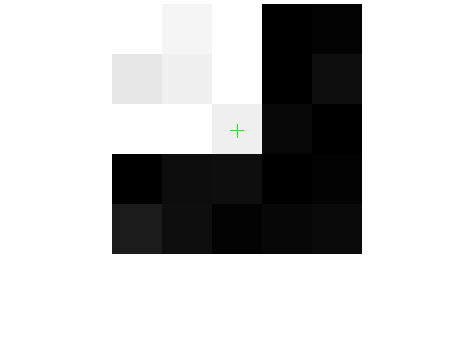

imshow(Image, InitialMagnification=5000);
hold on;
plot(corners.selectStrongest(2))
title('Corner Detected')